# **2108332 Adjustment Computation**

## **LAB 9** General Mathematical Model: Non-linear case

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

**การรังวัดค่าพิกัดของจุดบนเส้นตรง 6 จุด ได้ค่ารังวัดและค่าความเบี่ยงเบนมาตรฐานดังแสดงในตารางที่ 1 ในที่นี้กําหนดให้ค่ารังวัดทั้งหมดไม่มีสหสัมพันธ์**

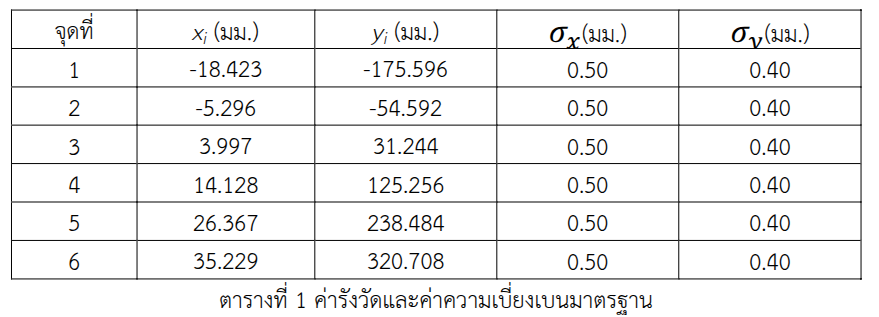

#### ต้องการปรับแก้ค่าพิกัดเพื่อหาค่าพารามิเตอร์ของเส้นตรงโดยวิธีกําลังสองน้อยที่สุด กําหนดให้ใช้ค่าประมาณสําหรับพารามิเตอร์ $a$และ $b$ เป็น 1.0 และ 0 ตามลำดับ การปรับแก้ต้องมีการวนซ้ําและจะหยุดเมื่อการปรับขนาดของพารามิเตอร์ $b$ น้อยกว่า 0.00001 $\left|x_b \right|<0\ldotp 00001$ สคริปต์ต้องแสดงค่าพารามิเตอร์ และค่ารังวัดที่ปรับแก้แล้ว

clc
clear
format long g

syms x1 x2 x3 x4 x5 x6 y1 y2 y3 y4 y5 y6 a b

lb = [-18.423, -175.596, -5.296, -54.592, 3.997, 31.244, 14.128, 125.256, 26.367, 238.484, 35.229, 320.708];

p = [1/0.5^2;1/0.4^2;1/0.5^2;1/0.4^2;1/0.5^2;1/0.4^2;1/0.5^2;1/0.4^2;1/0.5^2;1/0.4^2;1/0.5^2;1/0.4^2];
P = diag(p);

f1 = y1 - a * x1 - b;
f2 = y2 - a * x2 - b;
f3 = y3 - a * x3 - b;
f4 = y4 - a * x4 - b;
f5 = y5 - a * x5 - b;
f6 = y6 - a * x6 - b;

j_xa = jacobian([f1 f2 f3 f4 f5 f6],[a b]);
j_la = jacobian([f1 f2 f3 f4 f5 f6],[x1 y1 x2 y2 x3 y3 x4 y4 x5 y5 x6 y6]);

x0 = [1;0];
B0 = 1;
iteration = 0;

while abs(B0 - x0(2)) > 0.00001
    
    J_xa = subs(j_xa,[a b x1 y1 x2 y2 x3 y3 x4 y4 x5 y5 x6 y6],[x0(1) x0(2) lb]);
    J_la = subs(j_la,[a b x1 y1 x2 y2 x3 y3 x4 y4 x5 y5 x6 y6],[x0(1) x0(2) lb]);

    F0 = [subs([f1;f2;f3;f4;f5;f6],[a b x1 y1 x2 y2 x3 y3 x4 y4 x5 y5 x6 y6],[x0(1) x0(2) lb])];

    Fx = F0 - J_xa * x0;
    
    B0 = double(x0(2));

    xa = - (J_xa' * (J_la * P^-1 * J_la')^-1 * J_xa )^-1 * J_xa' * (J_la * P^-1 * J_la')^-1 * Fx;

    x0 = double(xa);

    iteration = iteration + 1;

end

v = double(- P^-1 * J_la' * (J_la * P^-1 * J_la')^-1 * (J_xa * xa + Fx));

x0

x0 =           9.25230939948645
         -5.44063849834004


la = lb' + v

la =          -18.3908232938716
         -175.598225724523
         -5.31221318724027
         -54.5908785027191
          3.96515504303956
           31.246202776796
          14.1258556307822
          125.256148330135
           26.363673979504
          238.484230067222
